## **Modelado de sistemas físicos**

Segunda ley de newton

syms v(t) g cd m 
eqn = diff(v,t) == g -(cd/m)*v^2;
cond = v(0) == 0;
vSym(t) = dsolve(eqn,cond)

$$vSym(t) = \frac{\sqrt{g}\,\sqrt{m}\,\tanh\left(\frac{\sqrt{\mathrm{cd}}\,\sqrt{g}\,t}{\sqrt{m}}\right)}{\sqrt{\mathrm{cd}}}$$

g = 9.81;
m = 68.1;
cd = 0.25;
vel = subs(vSym)

$$vel(t) = \frac{\sqrt{10}\,\sqrt{681}\,\sqrt{981}\,\tanh\left(\frac{\sqrt{10}\,\sqrt{681}\,\sqrt{981}\,t}{13620}\right)}{50}$$

fplot(vel,[0,12]) 
hold on
% tambien se puede hacer como
fin = 12

fin = 12

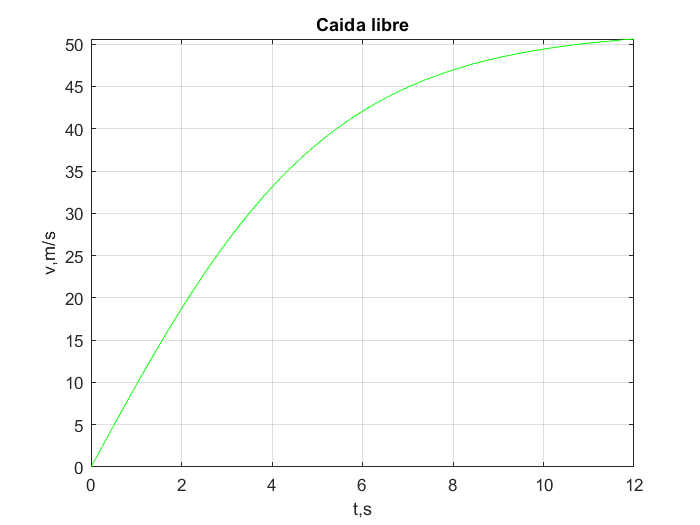

fplot(vel,[0 fin],'g')
hold on
xlabel('t,s')
ylabel('v,m/s')
grid on
title('Caida libre')

### Solución numérica.

*Método de euler*

v'(t) = g -cd/m * v^2

v(0) = 0

t  = 0:h:12

t =      0     1     2     3     4     5     6     7     8     9    10    11    12


size(t)

ans =      1    13


length(t)

ans = 13

v = zeros(1,length(t))

v =      0     0     0     0     0     0     0     0     0     0     0     0     0


Pero es mejor usar la otra notación donde obtenemos las dimensiones del arreglo

v = zeros(size(t));
g = 9.81;
cd = 0.25;
m = 68.1;
h = 1;
t = 0:h:12;
%a = @(v) g-(cd/m)*v^2 %funcion anónima

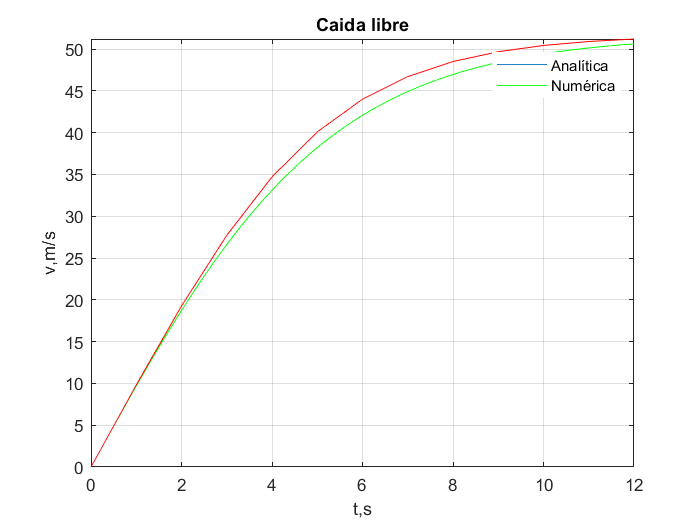

for i=2:length(t)
    v(i) = v(i-1) + caida_libre(g,cd,m,v(i-1));
end

v;
plot(t,v,'r');
legend('Analítica','Numérica')